# Power generation and Energy Budget

## A. Power Generated with other pointings pointing Vs Beta angle at an altitude

### 1. Calculation at multiple altitudes, case for orbital pointing mode

First, we will see what is the generated power at different altitudes, with the variation of the beta angle.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 1 in this section, because it corresponds to the orbital (nadir) pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 1;   %"sun-aero" pointing mode
% 1: "orbital" Reference quaternion is aligned with ORF. 
% 2: "sun-aero" Reference quaternion is such that x is aligned with velocity and z is aligned as best as possible with the sun direction to maximize the power generation 
% 3: "sun pointing" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction. 
% 4: "aero-drag" Reference quaternion is similar than in Case 1, but rotated 90° along the y axis, therefore, the reference quaternion is an attitude for maximizing the drag surface. 
% 5: "retrogade firing" Reference quaternion is similar than in Case 1, but rotated 180° along the z axis, therefore, the reference quaternion is an attitude for retrograde propulsion. (??should be like case 2 but rotated?)
% 6: Reference quaternion is static [1 0 0 0], but this time is the only case where the state of the B-dot is enabled (1). 
% 7: Reference quaternion is a custom quaternion that has to be defined by the user as an input to the mission block. 

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav(j,i)=mean(Pcollected);
        B(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode1.mat','B','Pav')  
        %load('power_from_b_alt_mode1.mat') %if we don't want to run the whole simulation again
        Pav=Pav_nadir;
        B=B_nadir;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

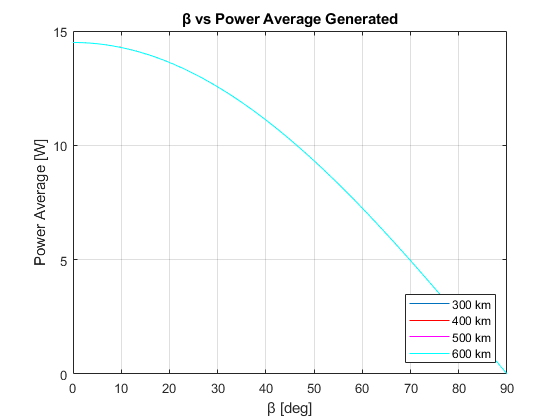

%Pav1=10:0.1:40;
Pav1=0:0.1:15;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,:),B(3,:),Pav1);
B4 = interp1(Pav(4,:),B(4,:),Pav1);

figure(1)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

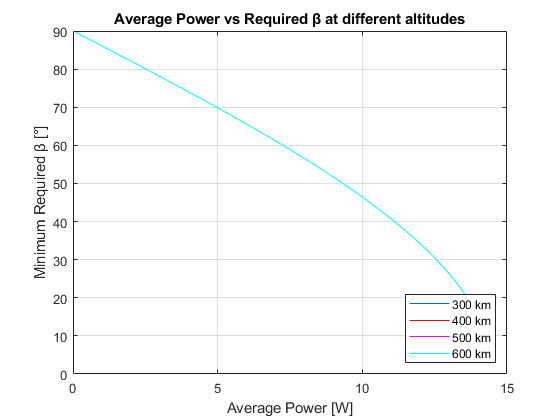

figure(2)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Minimum Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed

### 2. Calculation at multiple altitudes, case for sun-aero pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun-aero pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 2 in this section, because it corresponds to the sun-aero pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 2;   %"sun-aero" pointing mode

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_saero(j,i)=mean(Pcollected);
        B_saero(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode2.mat','B','Pav')  
        %load('power_from_b_alt_mode2.mat') %if we don't want to run the whole simulation again
        Pav = Pav_saero;
        B = B_saero;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

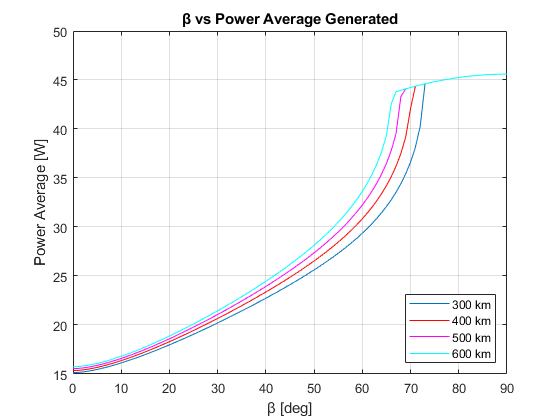

Pav1=10:0.1:40;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,:),B(3,:),Pav1);
B4 = interp1(Pav(4,:),B(4,:),Pav1);

close all

figure(3)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

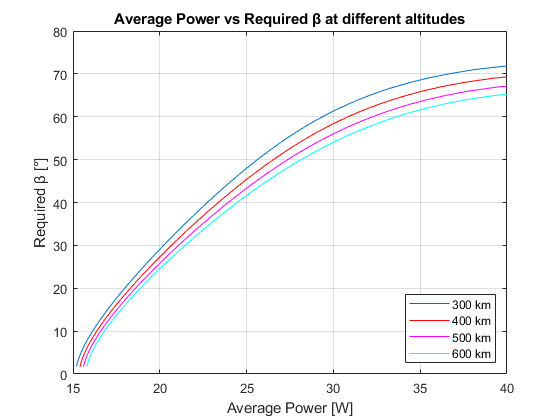

figure(4)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 3. Calculation at multiple altitudes, case for sun pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 3 in this section, because it corresponds to the aero-drag (aero-brake) pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 3;   %"sun pointing" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction.

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_sun(j,i)=mean(Pcollected);
        B_sun(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode3.mat','B_sun','Pav_sun')  
        %load('power_from_b_alt_mode3.mat') %if we don't want to run the whole simulation again
        Pav = Pav_sun;
        B = B_sun;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

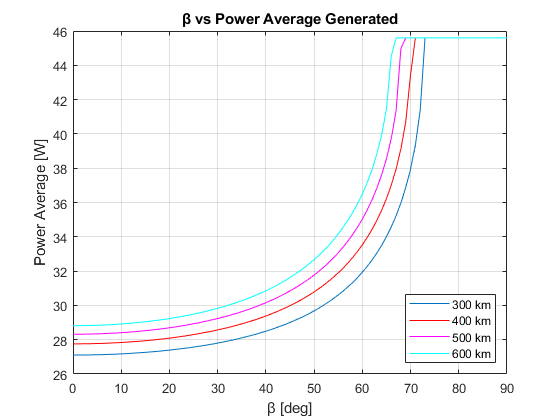

close all

figure(5)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

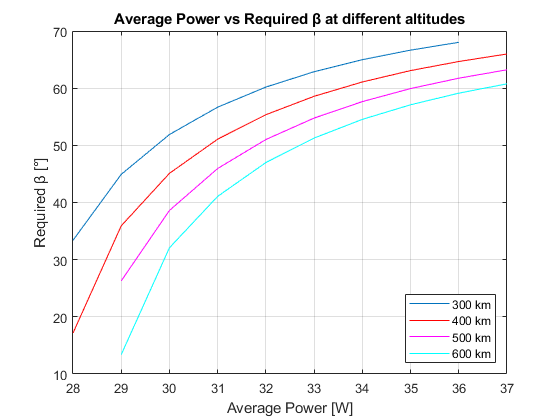

Pav1=28:1:45;
%Pav1=0:0.1:10.5;
B1 = interp1(Pav(1,1:70),B(1,1:70),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,1:68),B(2,1:68),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,1:65),B(3,1:65),Pav1);
B4 = interp1(Pav(4,2:62),B(4,2:62),Pav1);

figure(6)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 4. Calculation at multiple altitudes, case for aero-drag pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the aero-drag pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%.

The difference here is the pointing mode, that is set to 1 in this section, because it corresponds to the aero-drag (aero-brake) pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 4;   %"aero-drag" pointing mode

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_drag(j,i)=mean(Pcollected);
        B_drag(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %save('power_from_b_alt_mode4.mat','B','Pav')  
        %load('power_from_b_alt_mode4.mat') %if we don't want to run the whole simulation again
        Pav = Pav_drag;
        B = B_drag;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

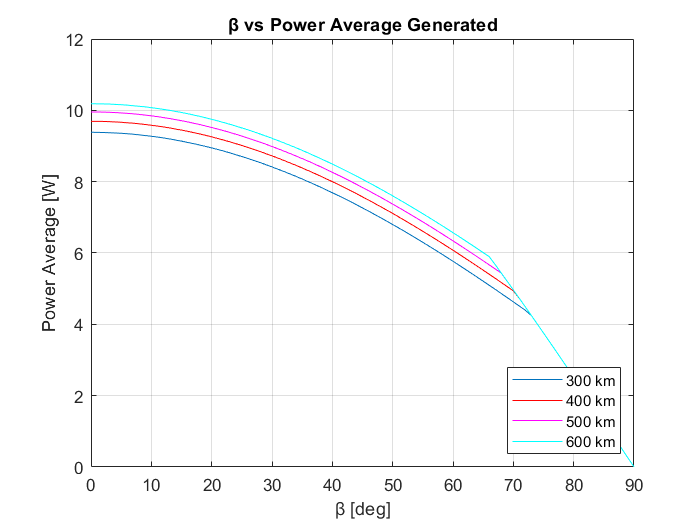

%Pav1=10:0.1:40;
Pav1=0:0.1:10.5;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,:),B(3,:),Pav1);
B4 = interp1(Pav(4,:),B(4,:),Pav1);

close all

figure(7)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on 

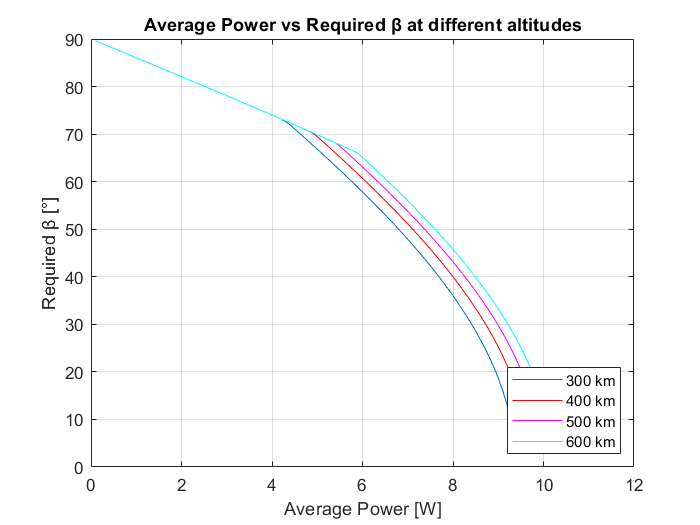

figure(8)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.